clear; close all; clc;

## Question 4) b)

[See derivation for matrices on hand calculations]

A = 1;
B = 2;
x0 = 3;
steps = 2;

Qbar = zeros(steps,steps);
Rbar = eye(steps);
H = [Qbar zeros(steps,steps); zeros(steps,steps) Rbar];
f = zeros(steps*2,1);
Abar = [zeros(1,steps-1); A*eye(steps-1)];
Abar = [Abar, zeros(steps,1)];
Bbar = B*eye(steps);
A0 = zeros(steps,1);
A0(1) = A;
Atilde = [Abar-eye(steps), Bbar];
Btilde = A0*x0;

Next, the equality constraints are implemented in MATLAB. The first equality constraint is the equation the system is subject to and the second is the desired end condition.

Aeq1 = Atilde;
Beq1 = -Btilde;
Aeq2 = [0 1 0 0];
Beq2 = 0;

Finally, run `quadprog` to find the optimal cost by minimizing the cost function.

xb = quadprog(H,f,[],[],[Aeq1; Aeq2],[Beq1; Beq2])


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


xb =     1.5000
         0
   -0.7500
   -0.7500


costArr = xb(steps+1:length(xb));
Jstar = sum(costArr.^2/2);

#### Part c)

In addition to all of the constraints listed above, now constrain the actuation magnitude to


$$|u_k |\le 0\ldotp 5$$


xc = quadprog(H,f,[],[],[Aeq1; Aeq2],[Beq1; Beq2],[-inf -inf -0.5 -.5]',[inf inf 0.5 .5]')


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>


xc =     1.5000
         0
   -0.4752
    0.7494


Using this constraint, we found there is no feasible solution since the system cannot return to zero within 2 steps, provided the current initial condition and cost function. 

#### Part d)

A slight modification is made from part c where only the first input is constrained such that:


$$\left|u_0 \right|\le 0\ldotp 5$$


xd = quadprog(H,f,[],[],[Aeq1; Aeq2],[Beq1; Beq2],[-inf -inf -0.5 -inf]',[inf inf 0.5 inf]')


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


xd =     2.0000
         0
   -0.5000
   -1.0000


We found that the optimal cost is larger than that for part b since an assymetric quadratic will cost more. 

#### part e)

Keeping the same initial condition as the base problem,  we the final time vary between 2 and 10:N= 2,3, . . . ,10.  In each case, x(N) = 0. There are no constraints on the control. 

JstarArr = [];
for steps = 2:10
    Qbar = zeros(steps,steps);
    Rbar = eye(steps);
    H = [Qbar zeros(steps,steps); zeros(steps,steps) Rbar];
    f = zeros(steps*2,1);
    Abar = [zeros(1,steps-1); A*eye(steps-1)];
    Abar = [Abar, zeros(steps,1)];
    Bbar = B*eye(steps);
    A0 = zeros(steps,1);
    A0(1) = A;
    Atilde = [Abar-eye(steps), Bbar];
    Btilde = A0*x0;

    Aeq1 = Atilde;
    Beq1 = -Btilde;
    Aeq2 = zeros(1,steps*2);
    Aeq2(steps) = 1;
    Beq2 = 0;

    xe = quadprog(H,f,[],[],[Aeq1; Aeq2],[Beq1; Beq2]);
    costarr = xe(steps+1:length(xe));
    costarr = costarr.^2/2;
    JstarArr(steps-1) = sum(costarr);
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

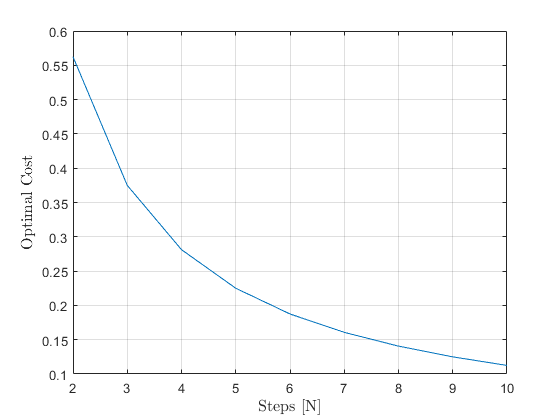

figure;
plot([2:10],JstarArr);
ylabel('Optimal Cost','Interpreter','Latex','FontSize',12)
xlabel('Steps [N]','Interpreter','Latex','FontSize',12)
grid on; box on;

table([2:10]',JstarArr','VariableNames',{'Steps'; 'Optimal Cost'})

ans = 9×2 table
    Steps    Optimal Cost
    _____    ____________

      2         0.5625   
      3          0.375   
      4        0.28125   
      5          0.225   
      6         0.1875   
      7        0.16071   
      8        0.14062   
      9          0.125   
     10         0.1125   
